clc;clear;close;

R = 0:0.2:10; % Pay attention to the selection of this step size
G0 = 1;
c_B = 10;

%%fix m, change l
m1 = 0.5

m1 = 0.5000

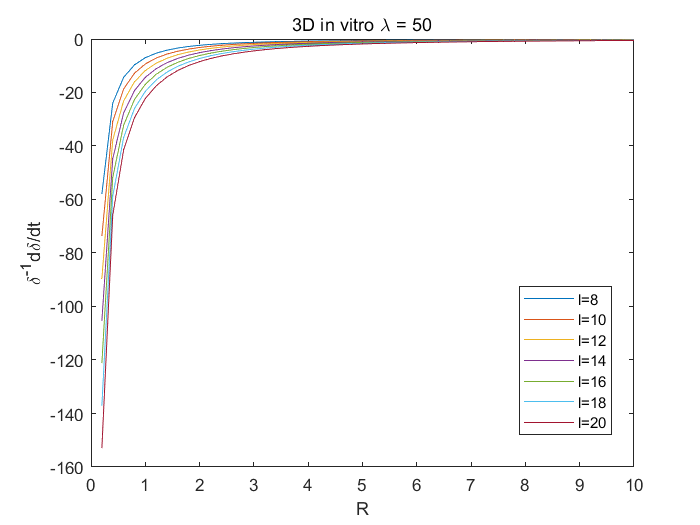

l = [8 10 12 14 16 18 20];

% lambda = 50;
lambda = 50;

for i=1:length(l)
    sigma1= vitro_3D(l(i),R,m1,lambda,c_B,G0);
    plot(R, sigma1)
    hold on
end

title('3D in vitro \lambda = 50')
legend('l=8','l=10','l=12','l=14','l=16','l=18','l=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
hold off

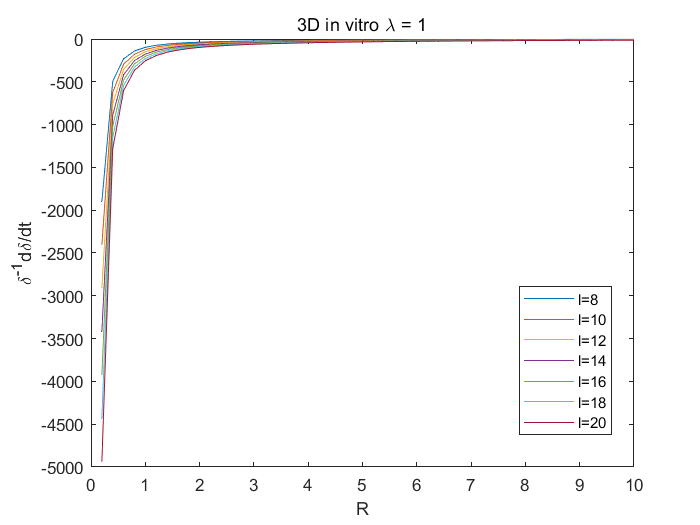


% lambda = 1;
lambda = 1;

for i=1:length(l)
    sigma1= vitro_3D(l(i),R,m1,lambda,c_B,G0);
    plot(R, sigma1)
    hold on
end

title('3D in vitro \lambda = 1')
legend('l=8','l=10','l=12','l=14','l=16','l=18','l=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
hold off

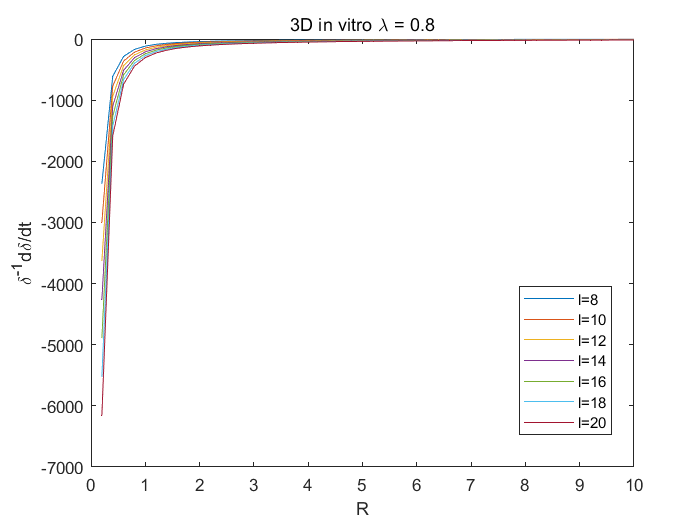


% lambda = 0.8;
lambda = 0.8;

for i=1:length(l)
    sigma1= vitro_3D(l(i),R,m1,lambda,c_B,G0);
    plot(R, sigma1)
    hold on
end

title('3D in vitro \lambda = 0.8')
legend('l=8','l=10','l=12','l=14','l=16','l=18','l=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
hold off

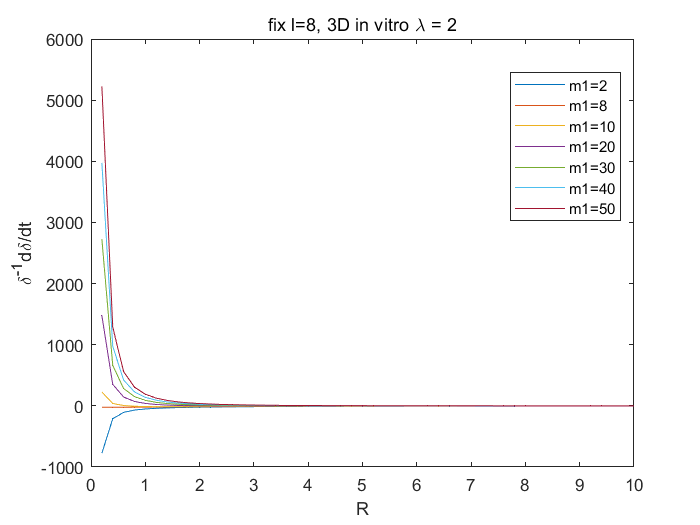


%%fix l change m
l=8;
m1 = [2 8 10 20 30 40 50];

lambda = 2;

for i=1:length(m1)
    sigma1= vitro_3D(l,R,m1(i),lambda,c_B,G0);
    plot(R, sigma1)
    hold on
end

title('fix l=8, 3D in vitro \lambda = 2')
legend('m1=2','m1=8','m1=10','m1=20','m1=30','m1=40','m1=50')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
hold off

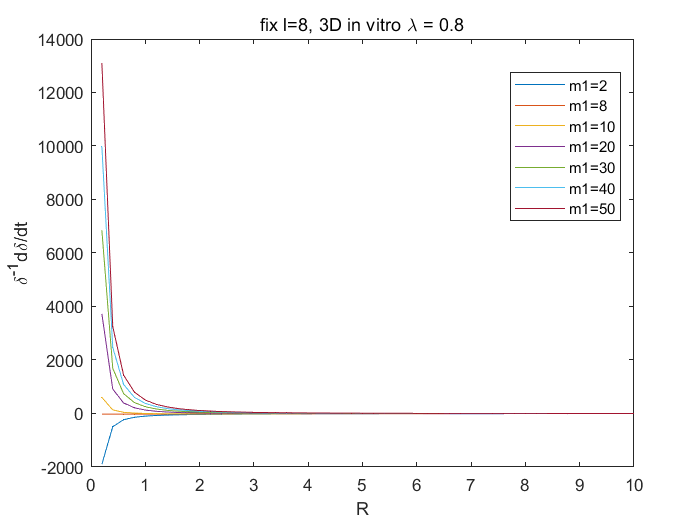



lambda = 0.8;
%c_B = 10;

for i=1:length(m1)
    sigma1= vitro_3D(l,R,m1(i),lambda,c_B,G0);
    plot(R, sigma1)
    hold on
end

title('fix l=8, 3D in vitro \lambda = 0.8')
legend('m1=2','m1=8','m1=10','m1=20','m1=30','m1=40','m1=50')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
hold off

function sigma1= vitro_3D(l,R,m,lambda,c_B,G0)
    A = (R.^(-1-m).* sinh(sqrt(lambda).*R) .* R.^(m+5/2) .* m .* sqrt(lambda))./2 ;
    B = (sqrt(lambda).*sqrt(R) + (lambda.^(3/2).* R.^(5/2))./2 ).* sinh(sqrt(lambda).*R) - cosh(sqrt(lambda).*R) .*lambda .* R.^(3/2);
    C1 =  -lambda .* (l+1) .* besseli(l+1/2,sqrt(lambda).*R);
    C2 =  besseli(l-1/2,sqrt(lambda).*R) .* lambda.^(3/2).*R  ;
    C =  ( C1 + C2).* R.^(5/2) .* cosh(sqrt(lambda).*R) ;
    % C =  ( C1 + C2).* R.^(5/2) .* cosh(sqrt(lambda).*R) ;
    D =  lambda^(3/2) .* R.^(7/2) .* sinh(sqrt(lambda).*R) .* besseli(l+1/2,sqrt(lambda).*R)  ;
    %sigma1 =c_B.*G0.* ( 2.*(A+B.*R) .* besseli(l+1/2,sqrt(lambda).*R)   - C./2 )./D;
    sigma1 =2.*c_B.*G0.* ( (A+B.*R) .* besseli(l+1/2,sqrt(lambda).*R)   - C./2 )./D;
end
